Clear Workspace

clear all; close all; clc;

## Initialize Parameters

g = 9.81;

%Scoring Coefficients
rWp = 2.25*10^(-1); %Revenue per unit payload weight
rVp = 3.00*10^2; %Revenue per unit payload volume
c_e = 8.33*10^(-8); %Cost per unit energy
c_c = 5.00*10^(-1); %Cost (COC) per flight
cWg = 6.74*10^1; %Cost per unit gross weight
c_f = 5.56*10^(-5); %Cost (FOC) per unit flight-time
t_l = 3.60*10^6; %Total flight time in aircraft life

%Design Variables
EWF = 0.65; %empty weight fraction
nb = 0.93; %efficiency
min_bat_charge = 0.1; %minimum battery charge
min_laps = 3;
max_laps = 5;
rho = 1.23; %density [kg/m^3]
alpha_max = 16; %degrees

%Limits
E_max = 71928*20*(1-min_bat_charge);
v_min = 0;
v_max = 25;
L2D_min = 10;
L2D_max = 15;
T_max = 11.12055; %max thrust [40 oz]
WL_min = 40;
WL_max = 130;


## Create Optimization Problem

prob = optimproblem;

## Define Design Variables

All values must be nonzero and positive

Wg = optimvar('Wg','LowerBound',0);
Tf = optimvar('Tf','LowerBound',0);
Ef = optimvar('Ef','LowerBound',0,'UpperBound',E_max);
Vp = optimvar('Vp','LowerBound',0);
Wp = optimvar('Wp','LowerBound',0);
v = optimvar('v','LowerBound',v_min,'UpperBound',v_max);
L2D = optimvar('L2D','LowerBound',L2D_min,'UpperBound',L2D_max);
WL = optimvar('WL','LowerBound',WL_min,'UpperBound',WL_max);

## Equations

Wp = Wg*(1-EWF);
%P = Ef/Tf;
Tf = (Ef*L2D)/(Wg*nb*v);
R = v*Tf/20;
Cd = T_max / (0.5*rho*v^2*(Wg/WL));
CL = L2D*Cd;


J = ((rWp*Wp + rVp*Vp - c_e*Ef - c_c)/(Tf))-((cWg*Wg)/(t_l))-c_f;

## Set the Objective

prob.Objective = J;
prob.ObjectiveSense = 'maximize';

## Constraints

prob.Constraints.Power = Ef/Tf <= 200;
prob.Constraints.Energy = Ef <= 20*71928*(1-min_bat_charge);
prob.Constraints.Time = Tf <= 20*3600*(19.98*(1-min_bat_charge))/(Ef/Tf);
prob.Constraints.Size = Vp <= 0.001;
prob.Constraints.Thrust = Wg/L2D <= T_max;
%prob.Constraints.MinPower = Ef/Tf >= 150; 
prob.Constraints.Laps = Tf <= 20*max_laps*600/v;
prob.Constraints.MinLaps = Tf >= 20*min_laps*600/v;
prob.Constraints.DragCoeff = Cd >= 0.05;
prob.Constraints.Maneuver = (Wg*sind(alpha_max) + 0.05*(0.5*rho*v^2*(Wg/WL))) <= T_max;
prob.Constraints.T2W_Low = T_max/Wg >= 0.5;
prob.Constraints.T2W_High = T_max/Wg <= 0.9;

## Check Problem

show(prob)


  OptimizationProblem : 

	Solve for:
       Ef, L2D, Vp, WL, Wg, v

	maximize :
       (((((((0.225 .* (Wg .* 0.35)) + (300 .* Vp)) - (8.33e-08 .* Ef)) - 0.5) ./ ((Ef .* L2D) ./ ((Wg .* 0.93) .* v))) - arg1) - 5.56e-05)

       where:

           arg1 = ((67.4 .* Wg) ./ 3600000);


	subject to Power:
       (Ef ./ ((Ef .* L2D) ./ ((Wg .* 0.93) .* v))) <= 200

	subject to Energy:
       Ef <= 1294704

	subject to Time:
       ((Ef .* L2D) ./ ((Wg .* 0.93) .* v)) <= (1294704 ./ (Ef ./ ((Ef .* L2D) ./ ((Wg .* 0.93) .* v))))

	subject to Size:
       Vp <= 0.001

	subject to Thrust:
       (Wg ./ L2D) <= 11.1205

	subject to Laps:
       ((Ef .* L2D) ./ ((Wg .* 0.93) .* v)) <= (60000 ./ v)

	subject to MinLaps:
       ((Ef .* L2D) ./ ((Wg .* 0.93) .* v)) >= (3

## Set Starting Point

initialPt.Ef = E_max;
initialPt.Tf = 3*60*20;
initialPt.Vp = 0.001;
initialPt.Wg = 10;
initialPt.L2D = 15;
initialPt.v = 20;
initialPt.WL = 1;

Check Feasibility

contraint_values = infeasibility(prob.Constraints.Power,initialPt)

contraint_values = 0

## Choose Algorithnm Options

options = optimoptions(prob,'Display','iter','PlotFcn',{@optimplotfval, @optimplotfirstorderopt});

## Solve Optimization Problem


Solving problem using fmincon.

Constraint derivatives calculated using forward mode automatic differentiation.

Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.379038e-04    9.452e+04    3.076e-03
    1       2   -6.273916e-05    5.884e+04    4.837e-03    4.573e+00
    2       3   -8.999559e-05    5.321e+04    5.314e-03    1.565e+00
    3       4   -8.931414e-05    5.284e+04    5.353e-03    2.350e-01
    4       5   -1.022684e-04    4.361e+04    6.520e-03    6.326e+00
    5       6   -1.026700e-04    4.348e+04    6.538e-03    3.641e-02
    6       7   -1.073757e-04    4.259e+04    6.668e-03    2.412e-01
    7       8   -1.668179e-04    3.442e+04    8.146e-03    2.753e+00
    8       9   -1.676509e-04    3.431e+04    8.172e-03    1.577e-01
    9      10   -2.657035e-04    2.54

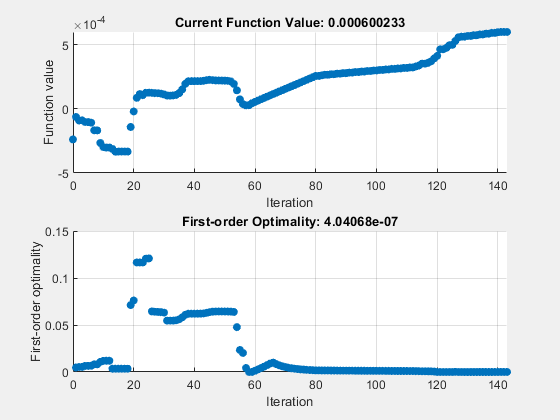

sol = struct with fields:
     Ef: 6.1987e+04
    L2D: 12.0109
     Vp: 9.9806e-04
     WL: 92.1058
     Wg: 22.2297
      v: 24.9909


sol = solve(prob,initialPt,'Options',options, "ObjectiveDerivative","auto",'ConstraintDerivative','auto')

## Check Solution

Tf_answer = ((sol.Ef * sol.L2D) / ((sol.Wg * 0.93) * sol.v))

Tf_answer = 1.4411e+03

Wp_Answer = (1-EWF)*sol.Wg

Wp_Answer = 7.7804